# Testing McCabe Complexity

This test can be used to qualify that the contents of a MATLAB project do not have exceedingly large cyclomatic complexity which can be a source of bugs.

## Use Interactively

To use interactively, while a [MATLAB project](https://www.mathworks.com/help/matlab/projects.html) is open, simply run the tests or create a TestSuite from the class and run it.

run(tMcCabeComplexity)

Running tMcCabeComplexity
.
Done tMcCabeComplexity
__________



ans =   TestResult with properties:

          Name: 'tMcCabeComplexity/shouldHaveLowComplexity(MaximumComplexity=Ten)'
        Passed: 1
        Failed: 0
    Incomplete: 0
      Duration: 0.2761
       Details: [1×1 struct]
Totals:
   1 Passed, 0 Failed, 0 Incomplete.
   0.27611 seconds testing time.

If it fails, the offending file information will be returned:

run(tMcCabeComplexity)

Running tMcCabeComplexity

Verification failed in tMcCabeComplexity/shouldHaveLowComplexity(MaximumComplexity=Ten).
    ----------------
    Test Diagnostic:
    ----------------
    McCabe Complexity of 215
    In: C:\Documents\MATLAB\Content\demos\HumanActivityRecognition\HelperFunctions\nhist.m
    ---------------------
    Framework Diagnostic:
    ---------------------
    verifyLessThan failed.
    --> The value must be less than the maximum value.
    
    Actual Value:
       215
    Maximum Value (Exclusive):
        10
    ------------------
    Stack Information:
    ------------------
    In C:\Documents\MATLAB\TestMcCabeComplexity\tMcCabeComplexity.m (tMcCabeComplexity.shouldHaveLowCompl

ans =   TestResult with properties:

          Name: 'tMcCabeComplexity/shouldHaveLowComplexity(MaximumComplexity=Ten)'
        Passed: 0
        Failed: 1
    Incomplete: 0
      Duration: 1.5077
       Details: [1×1 struct]
Totals:
   0 Passed, 1 Failed (rerun), 0 Incomplete.
   1.5077 seconds testing time.

## Use Interactively with External Parameters

A default allowable complexity of 10 is used.  If you would like to change this or use variable levels of complexity, this can be done using [external test parameters](https://www.mathworks.com/help/matlab/matlab_prog/use-external-parameters-in-parameterized-test.html).

import matlab.unittest.parameters.Parameter
import matlab.unittest.TestSuite
maxcomplexity = Parameter.fromData('MaximumComplexity', struct('Four', 4, 'Twelve', 12))

maxcomplexity =   1×2 Parameter array with properties:

    Property
    Name
    Value


TS = TestSuite.fromClass(?tMcCabeComplexity, 'ExternalParameters', maxcomplexity)

TS =   1×2 Test array with properties:

    Name
    ProcedureName
    TestClass
    BaseFolder
    Parameterization
    SharedTestFixtures
    Tags
Tests Include:
   2 Unique Parameterizations, 0 Shared Test Fixture Classes, 0 Tags.

run(TS)

Running tMcCabeComplexity

Verification failed in tMcCabeComplexity/shouldHaveLowComplexity(MaximumComplexity=Four#ext).
    ----------------
    Test Diagnostic:
    ----------------
    McCabe Complexity of 4
    In: C:\Documents\MATLAB\Content\demos\VirusDynamics\OOP\Step0_FullVersion\VirusData.m
    ---------------------
    Framework Diagnostic:
    ---------------------
    verifyLessThan failed.
    --> The value must be less than the maximum value.
    
    Actual Value:
         4
    Maximum Value (Exclusive):
         4
    ------------------
    Stack Information:
    ------------------
    In C:\Documents\MATLAB\TestMcCabeComplexity\tMcCabeComplexity.m (tMcCabeComplexity.shouldHaveLowCom

ans =   1×2 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details
Totals:
   1 Passed, 1 Failed (rerun), 0 Incomplete.
   1.329 seconds testing time.

## Using In Project

To use this test in automated workflows, add this to your MATLAB project and label it as "Test".  

- You can either add this repository as a submodule (recommended) or copy the `tMcCabeComplexity.m` file into your project.  Using a submodule will allow you to easily update in the future but does add project-level complexity.

- When a TestSuite is created from the project, it will be included if properly classified as "Test".  

                            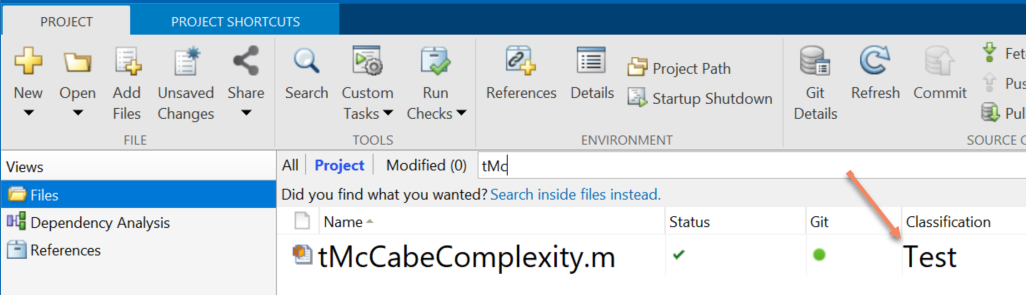

- If a file in the project is modified to be too complex, it will fail the build as a result.

TS = matlab.unittest.TestSuite.fromProject(currentProject)
run(TS)

*Copyright 2020 The MathWorks, Inc.*